7 Bar

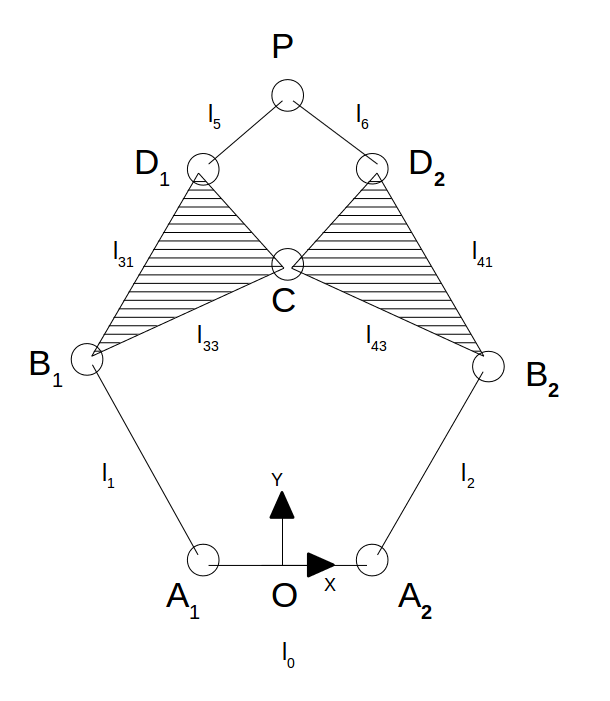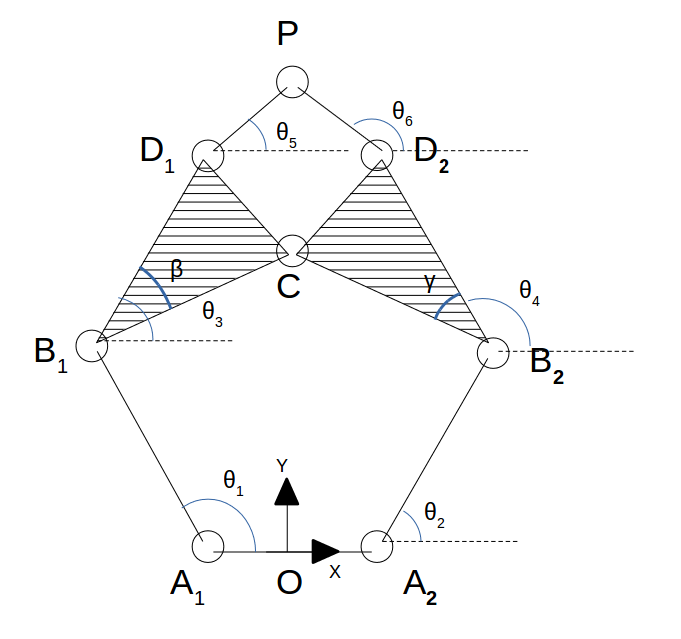

Constrainsts:

3 vector equations:


$${\mathrm{OA}}_1 +A_1 B_1 +B_1 D_1 +D_1 P=-\mathrm{OP}$$



$${\textrm{OA}}_2 +A_2 B_2 +B_2 D_2 +D_2 P=\textrm{OP}$$



$${{\textrm{A}}_1 \textrm{A}}_2 +A_1 B_1 +B_1 C+B_2 C+A_2 B_2 =0$$


6 scalar equations, 6 unknown angles $\theta_1 -\theta_6$

syms t1 t2 t3 t4 t5 t6

l0 = 2; l1 = 15; l2 = 15; l31 = 10; l33 = 10; l43 = 10; l41 = 10; l5 = 15; l6 = 15; 
%beta = deg2rad(15); gamma = deg2rad(15);
beta = 15; gamma = 15;

dist = linspace(0,5,3);
x = zeros(1,length(dist)); y = x; theta = [];
for i = 1:length(dist)
    x(i) = dist(i);
    y(i) = 2*x(i)^2 - 10*x(i) + 25;
    
    eq1a = x(i) + l0/2 + l2*cosd(t2) + l41*cosd(t4) + l6*cosd(t6) == 0;
    eq1b = y(i) + l2*sind(t2) + l41*sind(t4) + l6*sind(t6) == 0;
    
    eq2a = -x(i) + l0/2 + l1*cosd(t1) + l31*cosd(t3) + l5*cosd(t5) == 0;
    eq2b = -y(i) + l1*sind(t1) + l31*sind(t3) + l5*sind(t5) == 0;
    
    eq3a = l0 + l1*cosd(t1) + l2*cosd(t2) + l33*cosd(t4-beta) + l43*cosd(t4+gamma) == 0;
    eq3b = l1*sind(t1) + l2*sind(t2) + l43*sind(t4-beta) + l43*sind(t4+gamma) == 0;
    
    eqns = [eq1a, eq1b, eq2a, eq2b, eq3a, eq3b];
    
    [T1,T2,T3,T4,T5,T6] = vpasolve(eqns, [t1,t2,t3,t4,t5,t6]);
    
    theta = [theta; [T1,T2,T3,T4,T5,T6]];
end

theta

$$theta = \left(\begin{array}{cccccc} 118.17405365169536438990732521922 & -871.88372062535696774281830037316 & -938.33879809360680344275722044224 & 701.42502578510641734204728571969 & 381.81488940002091611358746005583 & 280.56715865836212642821054036737\\ -679.16315302755904624267342857325 & -2738.9812444945105634838906212983 & 1340.5511409299889520723010979461 & 2424.9862401613003606207949000654 & -1316.8296672318646044571228417484 & 1387.0335029745506929478323422113\\ 2227.7802831268626410999109669742 & -401.4798352834477325932650513921 & -16011.777797238143949983831527358 & -1248.1993911702171030817608714428 & -11103.251917147096237496544537632 & -839.77610813858380589340991575888 \end{array}\right)$$